# Multi Travelling Salesman Problem

The mathmatical formulation of the MTSP used in this solver is from: [https://www.tandfonline.com/doi/full/10.1080/21642583.2019.1674220#:~:text=Multiple%20Travelling%20Salesman%20Problem%20(MTSP,Computational%20solutions%20for%20TSP%20applications.](https://www.tandfonline.com/doi/full/10.1080/21642583.2019.1674220#:~:text=Multiple%20Travelling%20Salesman%20Problem%20(MTSP,Computational%20solutions%20for%20TSP%20applications.)

The second optimisation variable of f2 hasnt been solved in this code but would be a good subject of future work. I have briefly looked into using the fminimax solver to achieve this. 

## Define the Problem

Define the optimisation problem using the optiproblem function 

tic
MTSP = optimproblem;

## Define Cost Matrix

Define the number of cities and the number of salesman

C = number of cities, where Cij(1,1) is the start city

V = number of salesman

C = 10 ;
V = 3 ;

### Use this section of code to import gps coordinates

 It allows for file import and then a check to ensure data is in the right format

%  CoordsInput = uiimport ;
%  Coords = CoordsInput.data ;
%             
%             if size(Coords, 2) ~= 2
%                 fig = uifigure;
%                    uialert(fig,'Incorrect coordinate data dimensions. Must be a 2 column matrix','Invalid File') 
%             end


### Use this section of code to randomly generate gps coordinates between given lat and long boundaries 

The random generator is in the form (CoordA-CoordB).*rand+CoordA. CoordA is the lower value of the two

Coords= zeros(C+1,2); % Allocate coordinates of C in 2 column array
for i = 1:C+1
    xp = (-1.25+1.2).*rand-1.2;
    yp = (52.75-52.78).*rand+52.78;
        Coords(i, 2) = xp;
        Coords(i, 1) = yp;
end


Plot the location of the cities on a map of the earth 

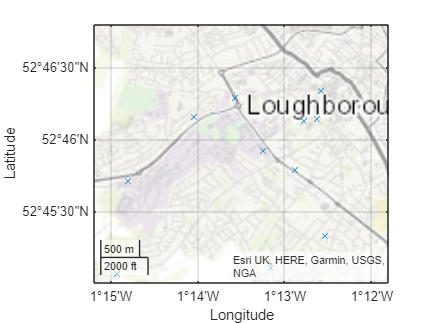

geoscatter(Coords(:,1),Coords(:,2),'x')
geobasemap topographic
geolimits([52.75 52.78], [-1.25 -1.2])

Find all the possible routes that can be travelled

trips = nchoosek(1:C+1,2);

### Calculate the distance between the points assuming they are on the surface of a sphere

Number of possible trips:

lengthtrips = length(trips);


Create matrix of distance coords in format [lat1, lon1, lat2, lon2]

journey = zeros(lengthtrips,4);
for i = 1: lengthtrips
    journey(i,:) = [Coords(trips(i,1),:), Coords(trips(i,2),:)];
end


Calculate the distance between the two cities in each possible journey

Define the shape of the earth using Reference ellipsoid for World Geodetic System of 1984

Earth = wgs84Ellipsoid("kilometer");

distjourney = zeros(lengthtrips,1);
for i = 1:lengthtrips
    distjourney(i) = distance(journey(i,1),journey(i,2),journey(i,3),journey(i,4), Earth);
end

Unable to use a value of type referenceEllipsoid as an index.

 Assign appropiate distances to the Cij Cost matrix

Cij = zeros(C+1,C+1);

for i = 1:lengthtrips
        Cij(trips(i,1),trips(i,2))=distjourney(i);
        Cij(trips(i,2),trips(i,1))=distjourney(i);
end

## Define Variables

Variables are defined using the optivar command. The varaibles are used to describe the problem objective and constraints


$$x_{\textrm{ijk}} =\left\lbrace \begin{array}{ll}
1 & \textrm{Salesman}\;k\;\textrm{passes}\;\textrm{from}\;\textrm{city}\;i\;\textrm{to}\;\textrm{city}\;j\\
0 & \textrm{else}
\end{array}\right.$$


Xijk = optimvar('Xijk', C+1,C+1,V, 'Type','integer','LowerBound',0,'UpperBound',1);

## Define the objective function

Use dot notation to define the objective function of the minimisation problem 


$$f_1 =\sum_{k=1}^m \sum_{i=0}^n \sum_{j=0}^n c_{\textrm{ij}} x_{\textrm{ijk}}$$


F = optimexpr(C+1,C+1,V);


Use for loop to step through each 'page' of the Xijk matrix to complete dot product

Method > https://uk.mathworks.com/matlabcentral/answers/144400-multiplying-a-2d-matrix-with-each-slice-of-3d-matrix


for k = 1:V
    F(:,:,k) = Xijk(:,:,k).*Cij ;
end


 Sum all distances in F1 to get total distance travelled by all salesman 

F = sum(F,'all');

MTSP.Objective = F;

## Define Constraints

Use dot notation to define the constraitns of the problem 

#### City only visited once

Below variables say each row from row 2 and column from column 2 for all slices must equal 1


$$\sum_{k=1}^m \sum_{i=1}^n x_{\textrm{ijk}} =1;\;\;\forall j=1,\ldotp \ldotp \ldotp ,n$$



$$\sum_{k=1}^m \sum_{j=1}^n x_{\textrm{ijk}} =1;\;\;\forall i=1,\ldotp \ldotp \ldotp ,n$$



XikRows = optimconstr(C)
for i = 2:C+1
    XikRows(i) = sum(sum(Xijk(i,:,:))) == 1;
end

XjkColls = optimconstr(C)
for j = 2:C+1
    XjkColls(j) = sum(sum(Xijk(:,j,:))) == 1;
end

MTSP.Constraints.XikRows = XikRows;
MTSP.Constraints.XjkColls = XjkColls;
% 
% show(XikRows)
% show(XjkColls)

####  All salesman start at city 1 

 The sum of row 1 and column 1 for all slices equals the number of salesmen


$$\sum_{k=1}^m \sum_{i=1}^n x_{\textrm{i0k}} =m$$



$$\sum_{k=1}^m \sum_{j=1}^n x_{0jk} =m$$


XikStart = sum(sum(Xijk(1,:,:),3)) == V;
XjkStart = sum(sum(Xijk(:,1,:),3)) == V;

MTSP.Constraints.XikStart = XikStart;
MTSP.Constraints.XjkStart = XjkStart;

% show(XikStart)
% show(XjkStart)


Each slice (ie salesman) has to have a departing and return leg

$\sum_{i\in S} \sum_{j\not\in S} x_{\textrm{ijk}} \ge 1;\;\forall k\in V,\forall S\sqsubseteq C$  - question about if i have done this one!

XikStartSheet = sum(Xijk(1,:,:)) == 1;
XjkStartSheet = sum(Xijk(:,1,:)) == 1;

MTSP.Constraints.XikStartSheet = XikStartSheet;
MTSP.Constraints.XjkStartSheet = XjkStartSheet;

% show(XikStartSheet)
% show(XjkStartSheet)

#### Salesman visiting a city must depart that city


$$\sum_{i=0}^n x_{\textrm{ipk}} -\sum_{j=0}^n x_{\textrm{pjk}} =0,\;k=1,\ldotp \ldotp \ldotp ,M,\;p=0,\ldotp \ldotp \ldotp ,n$$


ConnectJourney = optimconstr(C+1,C+1,V)
for i = 2:C+1
        for k = 1:V
            ConnectJourney(i,j,k) = sum(Xijk(i,:,k))-sum(Xijk(:,i,k)) == 0;
        end
end
MTSP.Constraints.ConnectJourney = ConnectJourney;


#### Salesman cannot travel to own city 

Set the diagonal of all matricies to zero

Diagonal  = optimconstr(C+1,C+1)
for i = 1:C+1
    for k = 1:V 
    Diagonal(i,i,k) = Xijk(i,i,k) == 0;
    end
end
MTSP.Constraints.Diagonal = Diagonal;

## Solve the Problem

Use the solve command to solve the optimisation platform 

sol = solve(MTSP);
sol.Xijk


## Display the results

Show the results of the optimisation problem

Create matrix of the distances travelled

Dist = Cij.*sol.Xijk;


Calculate total distance travelled by all salesman

TotalDist = sum(Dist,'all')


Calculate distance travelled by each salesman

SalesmanDist = zeros(V,1) ;
for k = 1:V
    SalesmanDist(k) = sum(sum((Cij.*sol.Xijk(:,:,k)),'all'),'all') ;
end


Distplay Values

SalesmanDist 


## Format Data

Manipulate the data from the optimisation solution to allow coordinate sets to be produced and then plotted on a geographical axis 

Tour = zeros((lengthtrips),2,V);
for k = 1:V
    for i = 1:C+1
        for j = 1:C+1
            if sol.Xijk(i,j,k) ==1
                Tour(i,:,k) = [Coords(i,:)];
            end
        end
    end
end



Convert numerical array to cell array

Tour = num2cell(Tour,[1 2]);
Tour = reshape(Tour, [V 1 1]);


Remove Zero elements

Add return to start city 


for k = 1:V
    for i = lengthtrips : -1 : 1
        if Tour{k,1}(i,1) == 0
            Tour{k,1}(i,:) = [];
        end
    end
    Tour{k,1} = [Tour{k,1}; Coords(1,:)];
end

### Plot the Results

Plot the results of the optimisation problem on a geo plot


hold on
for k = 1:V
    geoplot(Tour{k,1}(:,1),Tour{k,1}(:,2),'x-')
    % Creat export excel file for each journey where each sheet is a different journey
    writematrix(Tour{k,1}(:,1:2), 'JourneyCoords.xls', 'Sheet', k)
end


Can change the map background by changing the tag next to geobase map

geobasemap topographic
geolimits([52.75 52.78], [-1.25 -1.2])
text(Tour{1,1}(1,1), Tour{1,1}(1,2), 'Base Depot')

toc